# Practica01ApelidoNombre

Cambia el nombre del guión a Practica01tuapellidoNombre

% Manuel Hidalgo Carmona

## Paso 1

clear all; close all;
fichero='constitucion española.txt';
fid=fopen(fichero, 'r')

fid = 3

[words count]=fread(fid,inf,'*uint8');
fclose(fid)

ans = 0

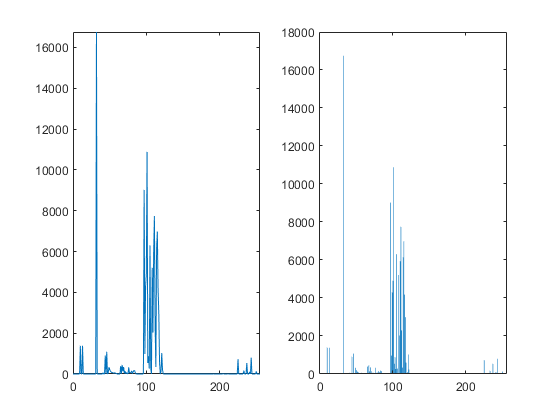

histograma= histc(words,[0:255]);
subplot(1,2,1);
plot([0:255],histograma); axis('tight')
% si prefieres puedes usar la función bar
subplot(1,2,2); bar([0:255],histograma)

## Paso 2

% A REALIZAR POR LOS ESTUDIANTES

% Crea la función entropiaTUSINICIALES(histograma)

% function y = entropiaMHC(histograma)
%     if ~isvector(histograma)
%         error("Error en fuc entropiaMHC: variable incompatible")
%     end
%     % distribucion de probabilidad
%     prod = histograma./sum(histograma)
%     % Calculo de la entropia
%     k = find(prod)
%     y = -sum(prod(k).*log2(prod(k)))
%     
% end

## Paso 3

H=entropiaMHC(histograma)

prod =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


k =     11
    14
    33
    35
    42
    45
    46
    47
    48
    49


y = 4.4880

H = 4.4880


% Debe salirte 4.4880.

## Paso 4

% A REALIZAR POR LOS ESTUDIANTES. RESPUESTA EN FICHERO PDF

% ¿Qué significa el valor de la entropía que has obtenido?. 
% ¿Cuál sería el factor de compresión que obtendríamos si usamos un modelo
% de codificación que alcanzase la entropía?. 
% ¿Podremos, a lo largo del curso, ganar a la entropía?

## Paso 5

clear all; close all;
A=imread('camera.pgm');
% Mostramos la imagen camera.pgm
subplot(1,2,1); imshow(A);

## Paso 6

histograma=histc(A(:),[0:255]);
subplot(1,2,2); bar([0:255],histograma)
entropiaMHC(histograma)

## Paso 7

% A REALIZAR POR LOS ESTUDIANTES. RESPUESTA EN FICHERO PDF

% ¿Qué significa el valor de la entropía que has obtenido?. 
% ¿Cuál sería el factor de compresión que obtendríamos si usamos un modelo
% de codificación que alcanzase la entropía?.

## Paso 8

clear all; close all; 
A=uint8(zeros(256));
A(1:128,:)=uint8(180);
subplot(1,2,1); imshow(A)
histograma= histc(A(:),[0:255]);
subplot(1,2,2); bar([0:255],histograma)
H=entropiaMHC(histograma)

## Paso 9

% A REALIZAR POR LOS ESTUDIANTES. RESPUESTA EN FICHERO PDF

% ¿Qué significa el valor de la entropía que has obtenido?. 
% ¿Cuál sería el factor de compresión que obtendríamos si usamos un modelo
% de codificación que alcanzase la entropía?. 
% ¿Podremos, a lo largo del curso, ganar a la entropía?

## Paso 10

% A REALIZAR POR LOS ESTUDIANTES. RESPUESTA EN FICHERO PDF

% Si hicieras más grande (y luego más chico) el cuadrado blanco, 
% ¿qué le pasaría  a la entropía?
% ¿Cuánto valdría la entropía si toda la imagen fuera blanca o negra? 
% ¿Qué significaría el valor de la entropía obtenido en este caso?.

## Paso 11

clear all; close all;
fichero='camera.pgm'
fid=fopen(fichero, 'r')
words=fread(fid,inf,'*uint16');
fclose(fid)
histograma= histc(words,[0:256*256-1]);
bar([0:256*256-1],histograma), axis('tight')
H=entropiaMHC(histograma)

## Paso 12

% A REALIZAR POR LOS ESTUDIANTES. INCLUYE TUS RESPUESTAS EN EL FICHERO PDF

% ¿Cuál es la entropía de esta fuente que codifica los símbolos de 
% ‘camera.pgm’ de dos en dos?. 
% ¿Qué significa el valor de la entropía que has obtenido?.

## Paso 13

clear all; close all;
fichero='camera.pgm'
fid=fopen(fichero, 'r')
words=fread(fid,inf,'*uint8');
fclose(fid)
histograma= histc(words,[0:255]);
H=entropiaMHC(histograma)

## Paso 14

% A REALIZAR POR LOS ESTUDIANTES. INCLUYE TUS RESPUESTAS EN EL FICHERO PDF

% Compara los valores de la entropía que has obtenido en los pasos 11 y 13. 
% ¿Qué está pasando?

## Paso 15

% A REALIZAR POR LOS ESTUDIANTES. INCLUYE TUS RESPUESTAS EN EL FICHERO PDF
% Y CÓDIGO AQUÍ

% Para los ficheros bird.pgm, ptt1.pbm, texto10000.txt, Cinco 
% semanas en globo - Julio Verne.txt crea una tabla con los nombres de los
% ficheros (filas) completa la siguiente tabla. ¿Qué significan los valores
% que obtienes?. Escribe el código correspondiente en el Paso 15 del fichero 
% Practica01ApellidoNombre (aqui).
clear all; close all;
fichreos=["bird.pgm","ptt1.pbm","texto10000.txt","Cinco semanas en globo - Julio Verne.txt"]

fichreos = 1×4 string array
    "bird.pgm"    "ptt1.pbm"    "texto10000.txt"    "Cinco semanas en globo - Julio Verne.txt"



for f = fichreos
    fid=fopen(f, 'r')
    wordsPO=fread(fid,inf,'*uint8');
    frewind(fid)
    wordsSO=fread(fid,inf,'*uint16');
    fclose(fid)
    disp('///////////////////////////////////////')
    disp(f)
    
    disp(['*******ENTROPIA PRIER ORDEN*******'])
    histogramaPO= histc(wordsPO,[0:255]);
    H1=entropiaMHC(histogramaPO)
    
    disp(['*******ENTROPIA SEGUNDO ORDEN******'])
    histogramaSO= histc(wordsSO,[0:256*256-1]);
    H2=entropiaMHC(histogramaSO)
end

fid = 3

ans = 0

///////////////////////////////////////


bird.pgm


*******ENTROPIA PRIER ORDEN*******


prod =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


k =     11
    12
    13
    15
    16
    17
    19
    20
    22
    23


y = 6.7752

H1 = 6.7752

*******ENTROPIA SEGUNDO ORDEN******


prod =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


k =         2828
        2829
        3084
        3085
        3087
        3597
        3599
        3600
        3601
        3603


y = 10.2581

H2 = 10.2581

fid = 3

ans = 0

///////////////////////////////////////


ptt1.pbm


*******ENTROPIA PRIER ORDEN*******


prod =     0.9322
    0.0027
    0.0000
    0.0029
    0.0000
         0
    0.0001
    0.0035
    0.0000
    0.0000


k =      1
     2
     3
     4
     5
     7
     8
     9
    10
    11


y = 0.6979

H1 = 0.6979

*******ENTROPIA SEGUNDO ORDEN******


prod =     0.9180
    0.0000
    0.0000
    0.0000
    0.0000
         0
    0.0001
    0.0003
    0.0000
         0


k =      1
     2
     3
     4
     5
     7
     8
     9
    11
    13


y = 1.1228

H2 = 1.1228

fid = 3

ans = 0

///////////////////////////////////////


texto10000.txt


*******ENTROPIA PRIER ORDEN*******


prod =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


k =     49
    50


y = 0.9999

H1 = 0.9999

*******ENTROPIA SEGUNDO ORDEN******


prod =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


k =        12337
       12338
       12593
       12594


y = 1.9998

H2 = 1.9998

fid = 3

ans = 0

///////////////////////////////////////


Cinco semanas en globo - Julio Verne.txt


*******ENTROPIA PRIER ORDEN*******


prod =          0
         0
         0
         0
         0
         0
         0
         0
         0
    0.0000


k =     10
    11
    14
    31
    33
    34
    40
    41
    42
    45


y = 4.4747

H1 = 4.4747

*******ENTROPIA SEGUNDO ORDEN******


prod =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


k =         2314
        2337
        2351
        2353
        2358
        2574
        3339
        3359
        3361
        3362


y = 7.8791

H2 = 7.8791

## Paso 16

A=imread('bird.pgm');

## Paso 17

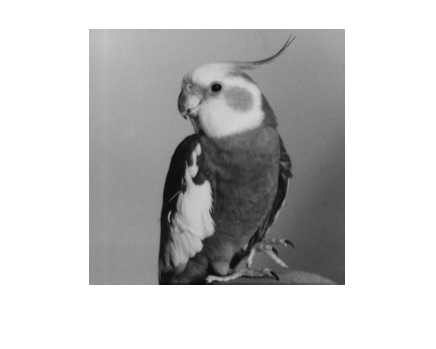

% A REALIZAR POR LOS ESTUDIANTES. INCLUYE CÓDIGO AQUÍ

%En el paso 17 del fichero Practica01ApellidoNombre.m escribe código para
%1.	Calcular  la entropía de la matriz que contiene la imagen. 
%2.	Calcular la diferencia de cada píxel con el anterior por filas.  
%    Es decir, vamos a calcular A(i,j)-A(i,j-1). No debes usar bucles y además
%    tienes que tener mucho cuidado con las diferencias ya que la diferencia 
%    de dos caracteres sin signo da un carácter sin signo y esto no es lo 
%    que queremos hacer. Para calcular la diferencia de la primera columna 
%    considera que la columna anterior es cero. 
%3.	Calcula también las diferencias módulo 256, es decir, 
%    (diferencias+256) módulo 256
%4.	Dibujar en una misma ventana la imagen de diferencias y su histograma. 
%5.	Dibujar también la imagen de (diferencias +256) módulo 256 y su histograma
%6.	Calcular la entropía de primer orden sobre la imagen de diferencias y 
%    sobre la imagen (diferencias +256) módulo 256 

%Nota 1: Ten cuidado con los tipos de datos cuando hagas diferencias 

%Nota 2: ¡Cuidado al calcular las diferencias! Para una imagen en escala de
%grises, las diferencias pueden estar en el intervalo [-255, 255] y por 
%tanto necesitamos al menos 9 bits para representarlas.  Esto no es 
%necesario en la imagen (diferencias +256) módulo 256

clear all; close all;
A=imread('bird.pgm');
imshow(A);

histograma=histc(A(:),[0:255]);
H=entropiaMHC(histograma)

prod =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


k =     12
    13
    15
    16
    17
    19
    20
    22
    23
    24


y = 6.7744

H = 6.7744


%Añadimos una fila de 0 al principio de la matriz
A1 = int16([zeros(1,size(A,2));A])

A1 = 257×256 int16 matrix
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   186   184   187   187   189   187   190   190   191   190   189   191   191   191   196   196   196   196   191   191   191   189   190   191   190   190   187   189   187   187   184   186   183   184   187   184   183   183   182   183   182   184   184   182   179   179   179   179   179   179
   183   184   186   186   189   187   190   190   190   189   187   191   193   190   194   194   194   194   190   193   191   187   189   190   190   190   187   189   186   186   184   183   184   186   186   184   183   183   184   183   180   183   184   183   180   183   180   180   179   177
   186   186   187   187   189   189   189   189   190   190   191   19

%Añadimos una fila de 0 al final de la matriz
A2 = int16([A(:,:);zeros(1,size(A,2))])

A2 = 257×256 int16 matrix
   186   184   187   187   189   187   190   190   191   190   189   191   191   191   196   196   196   196   191   191   191   189   190   191   190   190   187   189   187   187   184   186   183   184   187   184   183   183   182   183   182   184   184   182   179   179   179   179   179   179
   183   184   186   186   189   187   190   190   190   189   187   191   193   190   194   194   194   194   190   193   191   187   189   190   190   190   187   189   186   186   184   183   184   186   186   184   183   183   184   183   180   183   184   183   180   183   180   180   179   177
   186   186   187   187   189   189   189   189   190   190   191   191   190   193   193   193   193   193   193   190   191   191   190   190   189   189   189   189   187   187   186   186   187   187   183   183   184   186   184   184   182   182   184   180   179   180   180   180   179   177
   187   187   187   186   186   190   190   187   189   190   191   19


%Calculamos las diferencias y eliminamos la fila
%de ceros delfinal
Diferencias = A1-A2

Diferencias = 257×256 int16 matrix
   -186   -184   -187   -187   -189   -187   -190   -190   -191   -190   -189   -191   -191   -191   -196   -196   -196   -196   -191   -191   -191   -189   -190   -191   -190   -190   -187   -189   -187   -187   -184   -186   -183   -184   -187   -184   -183   -183   -182   -183   -182   -184   -184   -182   -179   -179   -179   -179   -179   -179
      3      0      1      1      0      0      0      0      1      1      2      0     -2      1      2      2      2      2      1     -2      0      2      1      1      0      0      0      0      1      1      0      3     -1     -2      1      0      0      0     -2      0      2      1      0     -1     -1     -4     -1     -1      0      2
     -3     -2     -1     -1      0     -2      1      1      0     -1     -4      0      3     -3      1      1      1      1     -3      3      0     -4     -1      0      1      1     -2      0     -1     -1     -2     -3     -3     -1      3      1     -1    

Diferencias(end,:) = []

Diferencias = 256×256 int16 matrix
   -186   -184   -187   -187   -189   -187   -190   -190   -191   -190   -189   -191   -191   -191   -196   -196   -196   -196   -191   -191   -191   -189   -190   -191   -190   -190   -187   -189   -187   -187   -184   -186   -183   -184   -187   -184   -183   -183   -182   -183   -182   -184   -184   -182   -179   -179   -179   -179   -179   -179
      3      0      1      1      0      0      0      0      1      1      2      0     -2      1      2      2      2      2      1     -2      0      2      1      1      0      0      0      0      1      1      0      3     -1     -2      1      0      0      0     -2      0      2      1      0     -1     -1     -4     -1     -1      0      2
     -3     -2     -1     -1      0     -2      1      1      0     -1     -4      0      3     -3      1      1      1      1     -3      3      0     -4     -1      0      1      1     -2      0     -1     -1     -2     -3     -3     -1      3      1     -1    

histogramaDife = histc(Diferencias(:),[-255:255]);
HDife = entropiaMHC(histogramaDife)

prod =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


k =     60
    65
    66
    67
    69
    70
    72
    73
    74
    76


y = 4.0224

HDife = 4.0224


%Calculamos la el modulo 256 de las diferencias
modulo = mod(Diferencias+256,256)

modulo = 256×256 int16 matrix
    70    72    69    69    67    69    66    66    65    66    67    65    65    65    60    60    60    60    65    65    65    67    66    65    66    66    69    67    69    69    72    70    73    72    69    72    73    73    74    73    74    72    72    74    77    77    77    77    77    77
     3     0     1     1     0     0     0     0     1     1     2     0   254     1     2     2     2     2     1   254     0     2     1     1     0     0     0     0     1     1     0     3   255   254     1     0     0     0   254     0     2     1     0   255   255   252   255   255     0     2
   253   254   255   255     0   254     1     1     0   255   252     0     3   253     1     1     1     1   253     3     0   252   255     0     1     1   254     0   255   255   254   253   253   255     3     1   255   253     0   255   254     1     0     3     1     3     0     0     0     0
   255   255     0     1     3   255   255     2     1     0     0 

histogramaMod256 = histc(modulo(:),[0:255]);
HMod256 = entropiaMHC(histogramaMod256)

prod =     0.2270
    0.1144
    0.0956
    0.0828
    0.0347
    0.0178
    0.0127
    0.0121
    0.0053
    0.0048


k =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


y = 4.0215

HMod256 = 4.0215


disp("Diferencias")

Diferencias


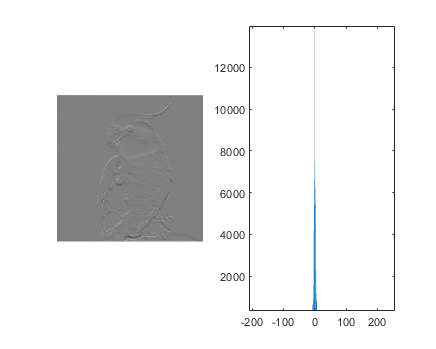

subplot(1,2,1);
imshow(Diferencias,[-255 255]);
subplot(1,2,2); 
bar([-255:255],histogramaDife)


disp("Diferencias mod 256")

Diferencias mod 256


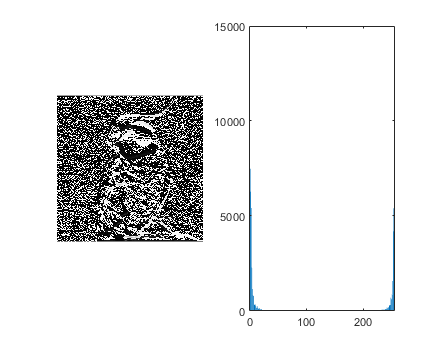

subplot(1,2,1,"replace")
imshow(modulo,[0 255]);
subplot(1,2,2)
bar([0:255],histogramaMod256)

## Paso 18

% A REALIZAR POR LOS ESTUDIANTES. INCLUYE TUS RESPUESTAS EN EL FICHERO PDF

% 1.	Incluye los gráficos del paso 17 aquí
% 2.	¿Cuál son las entropías de la imagen original, de la imagen de 
%       diferencias y de la imagen (diferencias+256) módulo 256 ? 
% 3.	Compáralas y explica el resultado 
% 4.	Si hubiese codificado las diferencias usando 
%       (diferencias+256) módulo 256, ¿podrías con esta codificación de
%       las diferencias reconstruir la señal original?

## Paso 19

% A REALIZAR POR LOS ESTUDIANTES. INCLUYE TUS RESPUESTAS EN EL FICHERO PDF

% Supongamos que tenemos una fuente que obtiene palabras de cuatro letras. 
% Supongamos además que las letras son generadas aleatoriamente suponiendo 
% una distribución uniforme sobre las 27 letras del abecedario. 
% ¿Cuántos bits necesitaríamos en media para representar cada palabra de 
% cuatro letras?.